## Non-parameteric regression

This file illustrates two common non-parametric regression approaches: kNN and decision trees (up to and including random forests). The goal is to show how "k" in kNN and the number of splits can be used to control the bias-variance trade-off in non-parametric methods. Bagging is also shown to decrease variance while maintaining flexibility (i.e., low bias)

clear
clf
newcolor = [228 26 28
            55 126 184
            77 175 74
            152 78 163
            255 127 0]/255

newcolor =     0.8941    0.1020    0.1098
    0.2157    0.4941    0.7216
    0.3020    0.6863    0.2902
    0.5961    0.3059    0.6392
    1.0000    0.4980         0


colororder(newcolor);

Generate a dataset with two inputs and one response variable, generated by a relatively smooth underlying function

rng(1)
fig = figure(); 
fig.Position(3:4) = [900, 300];
N = 80; % Observations per data set
M = 50; % Number of data sets

% Generating function
fz = @(x) 2 + tanh(0.5*(x(:,1)-5)) + exp(-(x(:,2) - 8).^2/20);

% Full data set, followed by partitioning using cross-validation function
XFull = [mvnrnd([2;3], [2, 0.1; 0.1, 2.5], M*N/2);
     mvnrnd([4;1], [1, -0.5; -0.5, 2], M*N/4);
     mvnrnd([0;0], [0.5, 0; 0, 0.5], M*N/4);] + [3 2];
zFull = fz(XFull) + 0.5*randn(N*M,1);
C = cvpartition(N*M, 'KFold', M);

In all subsequent sections, the `C.test` partition is used for training, and the `C.training` partition for testing. This is so that we can obtain a more accurate distribution over the prediction error using the larger `C.training` partition. The number of observations in the `C.test` partition is always equal to `N` defined above

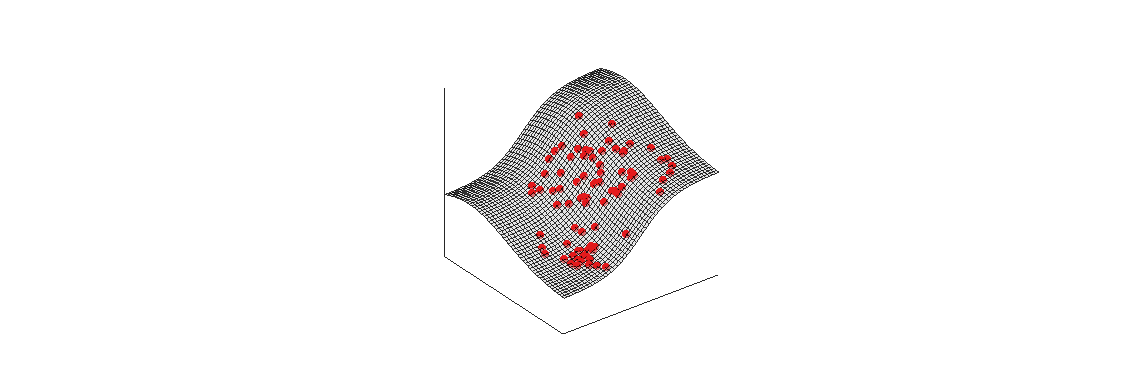

% Select and plot a single data set
i = 1;    
X = XFull(C.test(i),:);
z = zFull(C.test(i));

% Grid used to plot the generating function surface
NG = 50;
[xG, yG] = meshgrid(linspace(0,10,NG));
zG = reshape(fz([reshape(xG,[],1), reshape(yG,[],1)]), NG, []);

% Plot a single data set as well as the generating function
hold off
p = plot3(X(:,1), X(:,2), fz(X), '.');
p.MarkerSize = 15; p.Color = newcolor(1,:);
hold on

s = surf(xG,yG,zG);
s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];

a = gca(); a.XTick = []; a.YTick = []; a.ZTick = [];
axis([0 10 0 10 0 5]); axis square

Fit the surface using kNN for different values of k

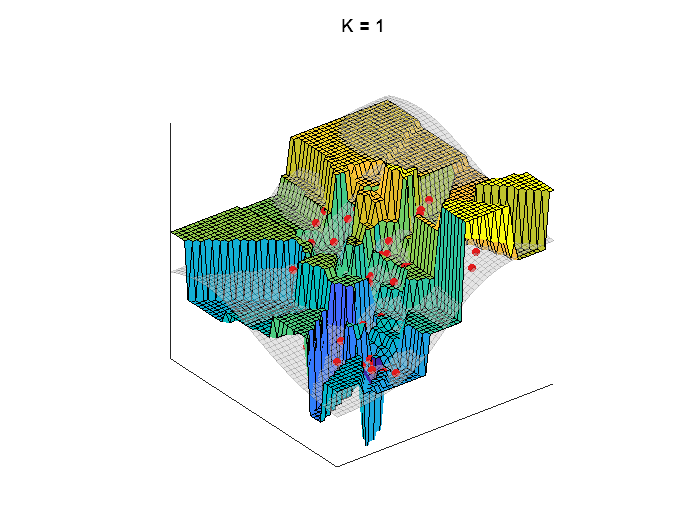

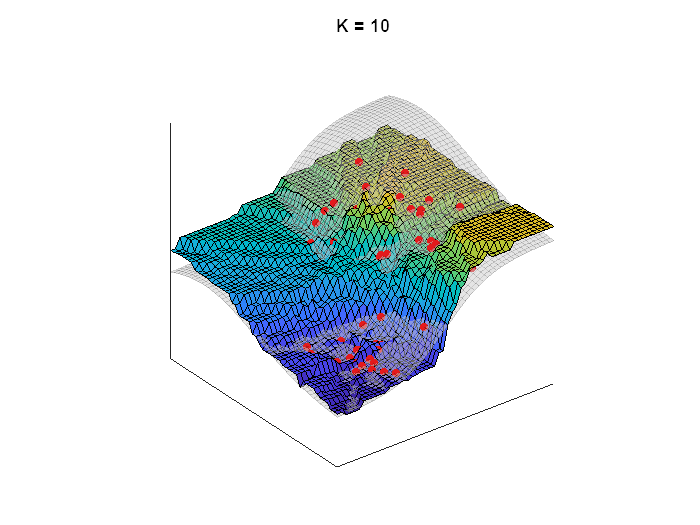

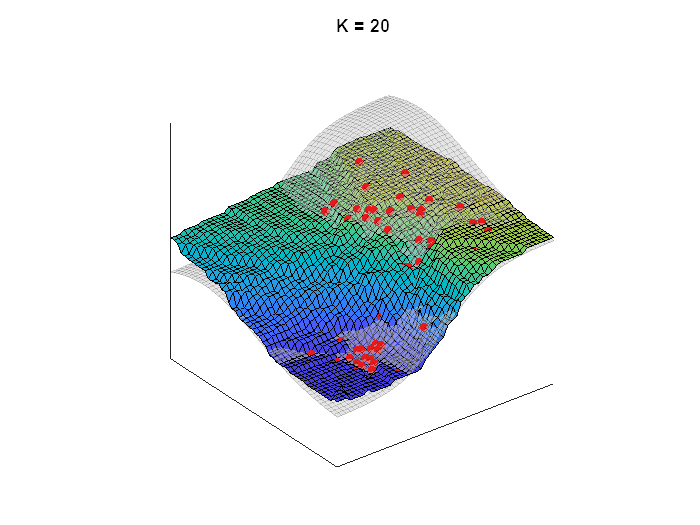

for K = [1, 10, 20]
    % Fit kNN
    zk = reshape(kNN([reshape(xG,[],1), reshape(yG,[],1)], X, z, K), NG, []);
    
    % Plot data, surface, and fitted function
    figure
    hold off
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.2; s.FaceColor = 0.8*[1 1 1];
    surf(xG, yG, zk)
    axis([0 10 0 10 0 5]); axis square
    a = gca(); a.XTick = []; a.YTick = []; a.ZTick = [];
    title(['K = ', num2str(K)]);
end

Fit the surfaces for multiple different data sets to demonstrate the variance for low k

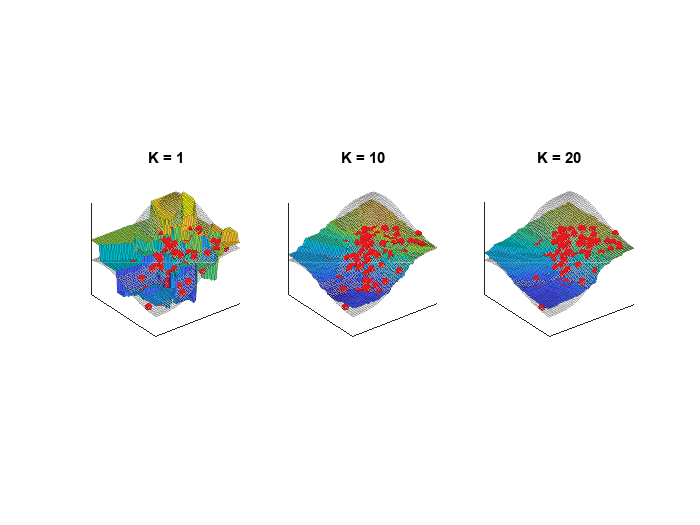

figure
for i = 1:M
    % Select dataset
    X = XFull(C.test(i),:);
    z = zFull(C.test(i));
    
    Kvec = [1, 10, 20];
    for j = 1:3
        % Fit kNN
        K = Kvec(j);
        zk = reshape(kNN([reshape(xG,[],1), reshape(yG,[],1)], X, z, K), NG, []);
        
        % Plot data, surface, and fitted function
        subplot(1,3,j)
        hold off
        p = plot3(X(:,1), X(:,2), fz(X), '.');
        p.MarkerSize = 15; p.Color = newcolor(1,:);
        hold on
        s = surf(xG,yG,zG);
        s.FaceAlpha = 0.5; s.EdgeAlpha = 0.2; s.FaceColor = 0.8*[1 1 1];
        s = surf(xG, yG, zk);
        s.EdgeAlpha = 0.2;
        axis([0 10 0 10 0 5]); axis square
        a = gca(); a.XTick = []; a.YTick = []; a.ZTick = [];
        title(['K = ', num2str(K)]);
    end

    drawnow

end

Calculate the prediction error for different value of k

K = round(N/2);     % Max k-value
MSE = zeros(M,K);
for k = 1:K
    for i = 1:M
        % Select data set
        X = XFull(C.test(i),:);
        z = zFull(C.test(i));
    
        % Fit kNN and evaluate error
        zk = kNN(XFull(C.training(i),:), X, z, k)';
        MSE(i,k) = mean( (zk - zFull(C.training(i))).^2 );
    end
end

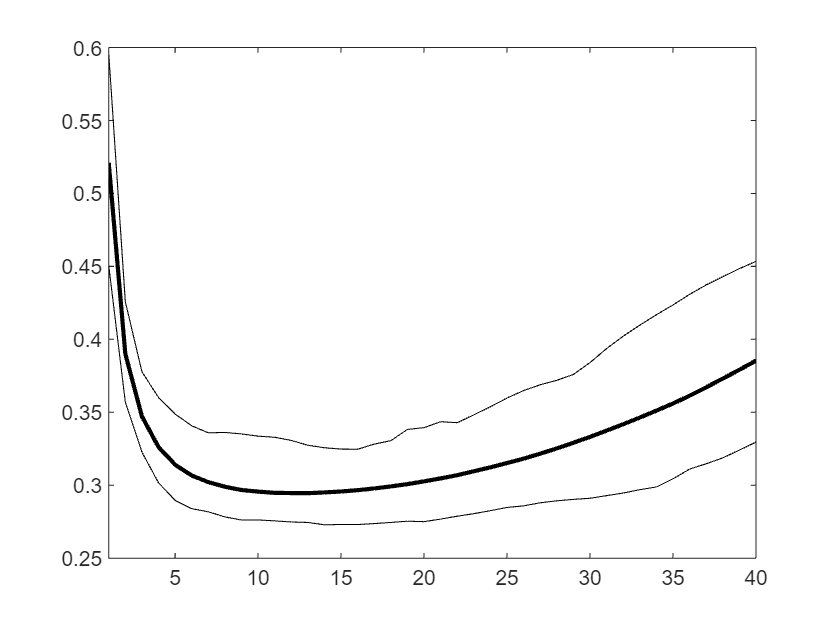

% Plot the MSE as a function of k
figure
hold off
p = plot(1:K, mean(MSE,1),'k', ...
         1:K, prctile(MSE, 5),'k',...
         1:K, prctile(MSE, 95),'k');
p(1).LineWidth = 2;
axis([1 K 0.25 0.6])

Fit decision trees while controlling the bias-variance trade-off through the number of possible splots

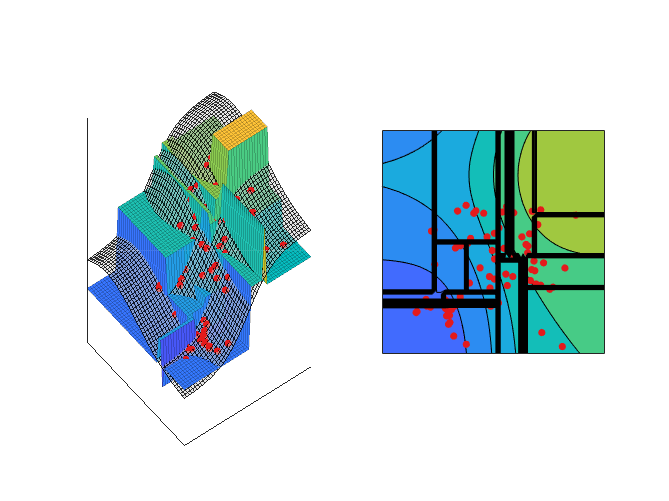

K = 20; % Maximum number of splits

% Select a data set
i = 3;
X = XFull(C.test(i),:);
z = zFull(C.test(i));

% Train decision tree using increasing number of splits
figure
for k = 1:K
    % Train decision tree and plot surface
    Mdl = fitrtree(X,z,'MinLeafSize',1,'MaxNumSplits',k,'MinParentSize',2);
    zk = reshape(predict(Mdl, [reshape(xG,[],1), reshape(yG,[],1)]), Nk, []);
    
    % Plot 3D surface
    subplot(1,2,1)
    hold off
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    s = surf(xG, yG, zk);
    s.EdgeAlpha = 0.2;
    axis([0 10 0 10 0 5]); %axis square
    caxis([0 5]);
    a = gca(); a.XTick = []; a.YTick = []; a.ZTick = [];
    title(['Number of splits: ', num2str(k)]); 

    % Illustrate splits on a contour graph
    subplot(1,2,2)
    contourf(xG,yG,zG);
    hold on
    p = plot(X(:,1), X(:,2), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    [~,c] = contour(xG, yG, zk, linspace(0,5,200));
    c.LineColor = 'k';
    axis([0 10 0 10 0 5]); axis square
    caxis([0 5]);
    a = gca(); a.XTick = []; a.YTick = [];
    
    drawnow

end

Calculate the prediction error for a varying number of splits, over multiple data sets

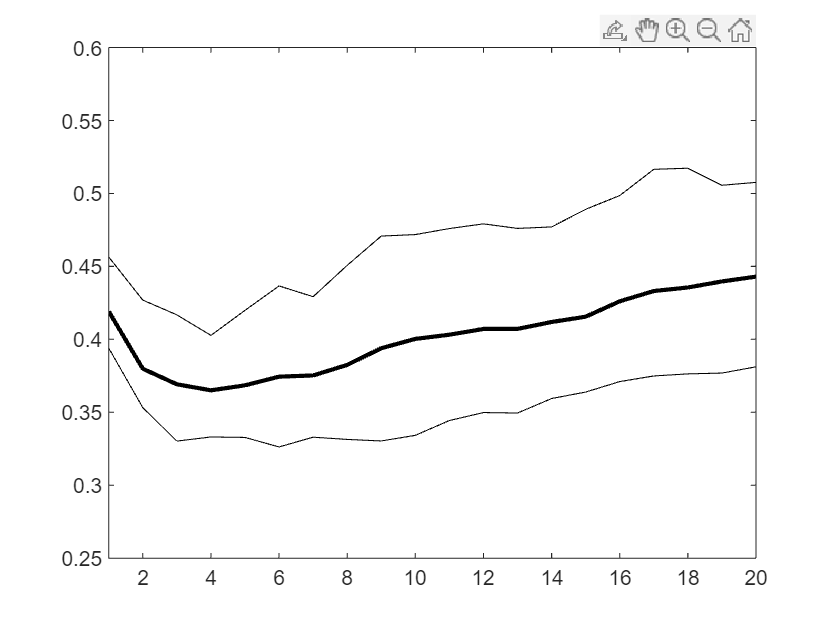

MSE = zeros(M,K);
for k = 1:K % Vary number of splits
    for i = 1:M % Vary datasets
        % Select data
        X = XFull(C.test(i),:);
        z = zFull(C.test(i));
    
        % Fit model and calculate test MSE using remaining data
        Mdl = fitrtree(X,z,'MinLeafSize',1,'MaxNumSplits',k,'MinParentSize',2);
        zk = predict(Mdl, XFull(C.training(i),:));
        MSE(i,k) = mean( (zk - zFull(C.training(i))).^2 );
    end
end

figure
hold off
p = plot(1:K, mean(MSE,1),'k', ...
         1:K, prctile(MSE, 5),'k',...
         1:K, prctile(MSE, 95),'k');
p(1).LineWidth = 2;
axis([1 K 0.25 0.6])

Illustrate bagging. Nine trees are trained using bootstrapped data, and the trees are averaged to give a bagged forest. In all cases, maintain low bias trees by setting the number of splits equal to a high number.

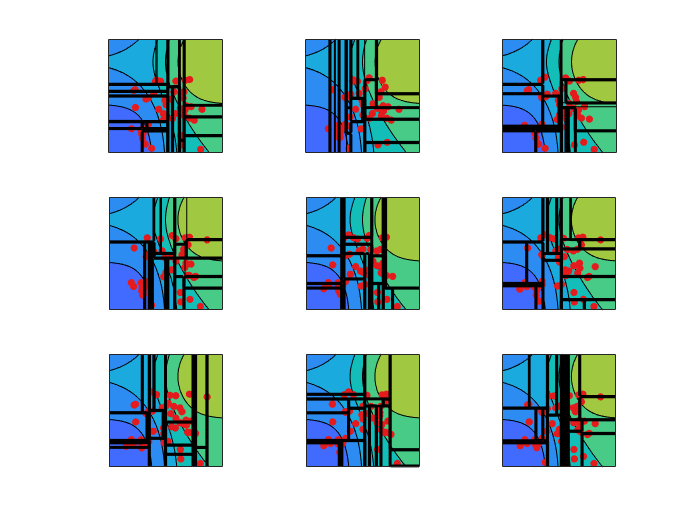

rng(1)
K = 20; % Number of splits

% Training data
i = 3;
idx = find(C.test(i));

figure
z_ave = 0*xG;
for l = 1:9
    
    % Bootstrap selection from the training data set
    boot_idx = idx(randsample(N,N,true));
    X = XFull(boot_idx,:);
    z = zFull(boot_idx);
    
    % Fit individual tree
    Mdl = fitrtree(X,z,'MinLeafSize',1,'MaxNumSplits',20,'MinParentSize',2);
    zk = reshape(predict(Mdl, [reshape(xG,[],1), reshape(yG,[],1)]), NG, []);
    
    % Add tree prediction to average prediction
    z_ave = z_ave + zk/9;

    % Plot individual tree as a contour graph
    subplot(3,3,l)
    contourf(xG,yG,zG);
    
    hold on
    p = plot(X(:,1), X(:,2), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    [~,c] = contour(xG, yG, zk, linspace(0,5,200));
    c.LineColor = 'k';
    axis([0 10 0 10 0 5]); axis square
    caxis([0 5]);
    a = gca(); a.XTick = []; a.YTick = [];
    
end

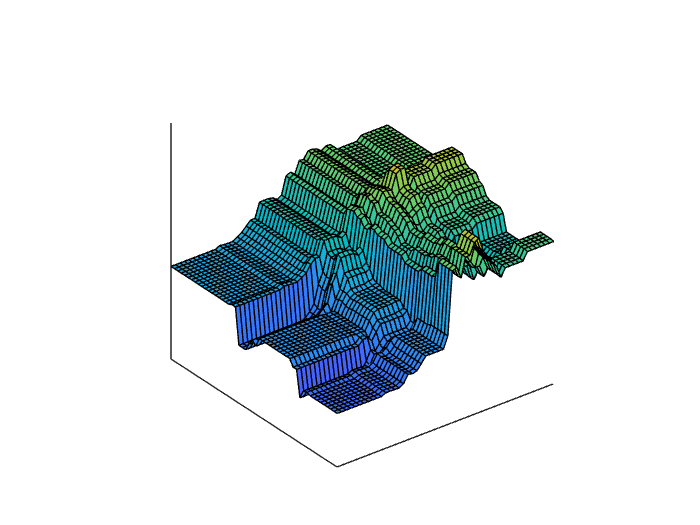


% Plot bagged forest
figure
surf(xG, yG, z_ave);
axis([0 10 0 10 0 5]); axis square
caxis([0 5]);
a = gca(); a.XTick = []; a.YTick = []; a.ZTick = [];

Determine MSE vs number of learners in a random forest, retaining individual flexibility with a high split number on individual trees

learners = 20; % Max number of learners

MSE_forest = zeros(M,learners);
template = templateTree('MinLeafSize',1,'MaxNumSplits',K,'MinParentSize',2);
for l = 1:learners
    for i = 1:M
        % Select data set
        X = XFull(C.test(i),:);
        z = zFull(C.test(i));
    
        % Train model with "l" learners
        Mdl = fitrensemble(X,z,'Method','Bag','Learner',template,'NumLearningCycles', l);
        
        % Calculate prediction error
        zk = predict(Mdl, XFull(C.training(i),:));
        MSE_forest(i,l) = mean( (zk - zFull(C.training(i))).^2 );
    end
end

Plot the resulting MSE as a function of learners, showing steady decrease in MSE (bias is not increased as variance is reduced)

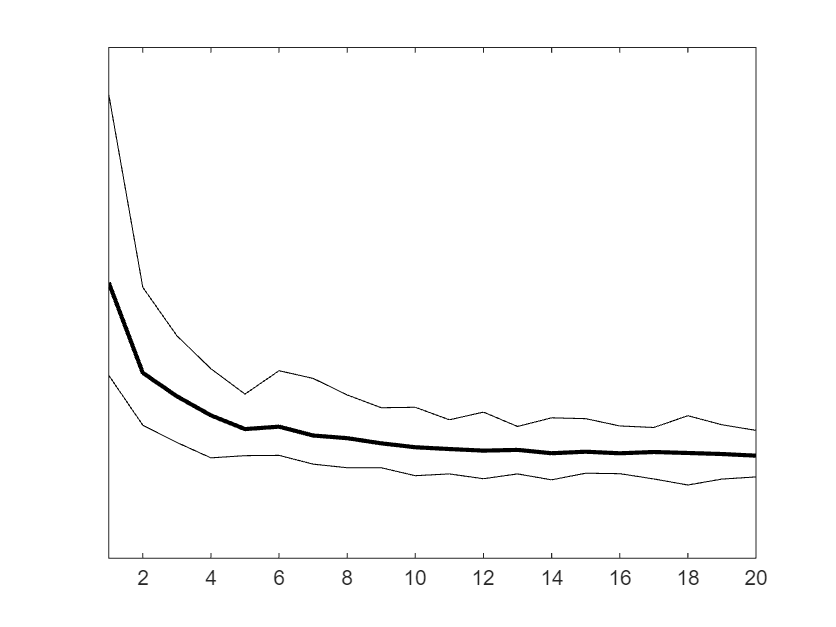

figure
p = plot(1:K, mean(MSE_forest,1),'k', ...
         1:K, prctile(MSE_forest, 5),'k',...
         1:K, prctile(MSE_forest, 95),'k');
p(1).LineWidth = 2;
axis([1 learners 0.2 0.8])
a = gca(); a.YTick = [];

Train a good random forest (deep trees, many learners), and show how the prediction at a query point is different for a single decision tree as opposed to a random forest

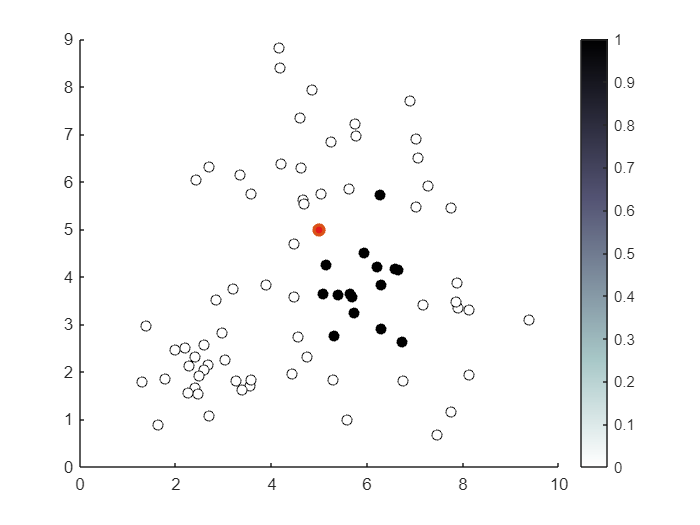

% Select data
i = 4;
X = XFull(C.test(i),:);
z = zFull(C.test(i));

% Fit a decision tree, then make predictions from the tree to the data
% points as well a single query point
K = 20;
learners = 100;
Mdl = fitrtree(X,z,'MinLeafSize',1,'MaxNumSplits',K,'MinParentSize',2);
zD = resubPredict(Mdl);     % Prediction at data points
z0 = predict(Mdl, [5 5]);   % Prediction at query point

% Identify data points that give the same prediction as the query point:
% these share a common leaf
I = find(zD == z0);
sens = zeros(N,1); sens(I) = 1;

% Plot the weighting from individual data points on the query point
figure
colormap(flipud(colormap('bone')));
hold off
scatter(X(:,1), X(:,2),[],sens,'MarkerFaceColor','flat', 'MarkerEdgeColor','k')
caxis([0 1])
hold on
plot(5,5,'o','LineWidth',2,'MarkerFaceColor',newcolor(1,:));
colorbar

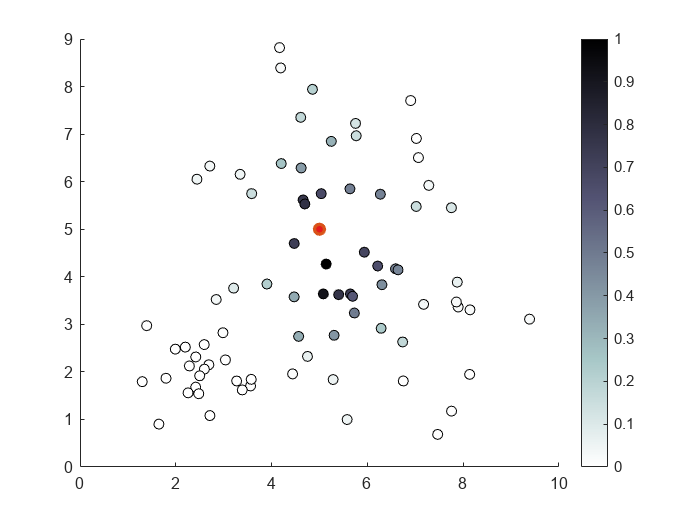


% Repeat the procedure above, but using a random forest
% Fit the model
template = templateTree('MinLeafSize',1,'MaxNumSplits',K,'MinParentSize',2);
Mdl = fitrensemble(X,z,'Method','Bag','Learner',template,'NumLearningCycles', learners);
sens_mat = zeros(learners, N);

% For each learner, identify data points that give the same prediction as the query point:
% these share a common leaf
for j = 1:learners
    subMdl = Mdl.Trained{j};
    zD = predict(subMdl, X);
    z0 = predict(subMdl, [5 5]);
    I = find(zD == z0);
    sens_mat(j, I) = 1;
end
% Average the contribution from each data point over all learners
sens = sum(sens_mat, 1); sens = sens/max(sens);

% Plot the weighting from individual data points on the query point
figure
colormap(flipud(colormap('bone')));
hold off
scatter(X(:,1), X(:,2),[],sens,'MarkerFaceColor','flat', 'MarkerEdgeColor','k')
caxis([0 1])
hold on
plot(5,5,'o','LineWidth',2,'MarkerFaceColor',newcolor(1,:));
colorbar

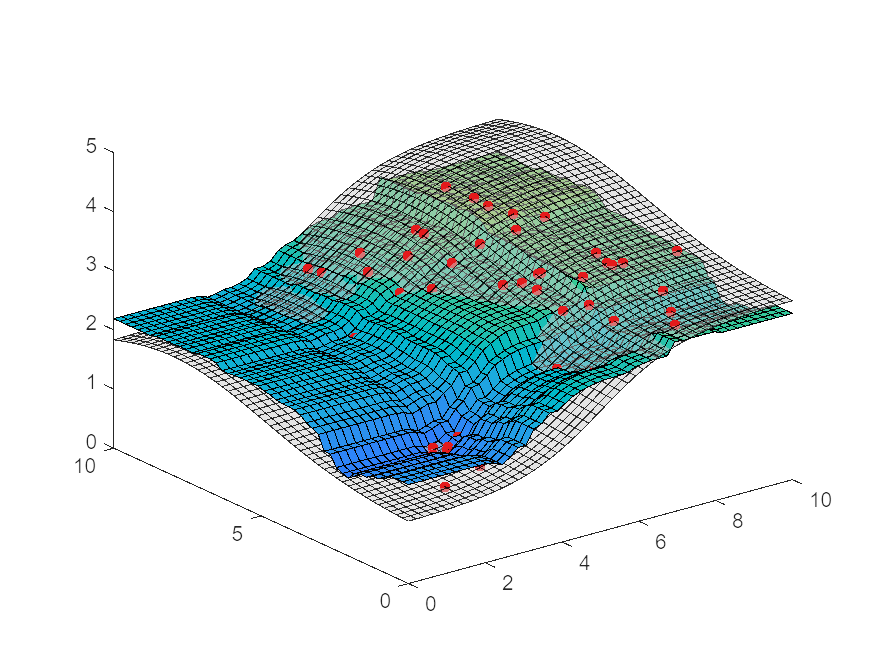


% Plot a large figure showing the trained random forest
zk = reshape(predict(Mdl, [reshape(xG,[],1), reshape(yG,[],1)]), NG, []);

figure
p = plot3(X(:,1), X(:,2), fz(X), '.');
p.MarkerSize = 15; p.Color = newcolor(1,:);
hold on
s = surf(xG,yG,zG);
s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
surf(xG, yG, zk)
axis([0 10 0 10 0 5]); %axis square
caxis([0 5]);


Compare the variance of single trees vs a random forest on multiple data sets

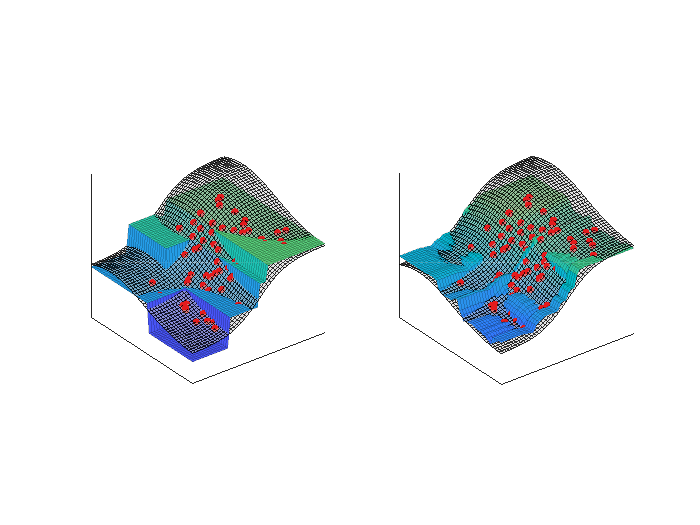

figure
for i = 1:20
    X = XFull(C.test(i),:);
    z = zFull(C.test(i));
    
    % Fit a decision tree
    Mdl = fitrtree(X,z,'MinLeafSize',1,'MaxNumSplits',K,'MinParentSize',2);
    zk = reshape(predict(Mdl, [reshape(xG,[],1), reshape(yG,[],1)]), Nk, []);
    
    % Plot the single decision tree fit
    subplot(1,2,1)
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    s = surf(xG, yG, zk);
    s.EdgeAlpha = 0.2;
    axis([0 10 0 10 0 5]); axis square
    caxis([0 5]);
    a = gca(); a.XTick = []; a.YTick = []; a.ZTick = [];
    hold off
    drawnow

    % Fit a random forest
    Mdl = fitrensemble(X,z,'Method','Bag','Learner',template,'NumLearningCycles', learners);
    zk = reshape(predict(Mdl, [reshape(xG,[],1), reshape(yG,[],1)]), Nk, []);
    
    % Plot the random forest fit
    subplot(1,2,2)
    p = plot3(X(:,1), X(:,2), fz(X), '.');
    p.MarkerSize = 15; p.Color = newcolor(1,:);
    hold on
    s = surf(xG,yG,zG);
    s.FaceAlpha = 0.5; s.EdgeAlpha = 0.8; s.FaceColor = 0.8*[1 1 1];
    s = surf(xG, yG, zk);
    s.EdgeAlpha = 0.2;
    axis([0 10 0 10 0 5]); axis square
    caxis([0 5]);
    a = gca(); a.XTick = []; a.YTick = []; a.ZTick = [];
    hold off
    
    drawnow


end

Function used in kNN regression

function y = kNN(x, xData, yData, K)
    D = pdist2(x, xData);
    [~, I] = sort(D, 2);
    for i = 1:length(x)
        y(i) = mean(yData(I(i, 1:K)));
    end
end